# Kohn-Sham DFT

## Main Limitation of Orbital-Free DFT

In these notes we will derive Kohn-Sham (KS) equations and implement simple numerical KS-DFT solver, based on real-space finite differnce method, for many-electron systems with spherically symmetric ground state electron density, such as a single atom with filled subshells.

The nonrelativistic Hamiltonian of a generic $N$-electron system, assuming Born-Oppenheimer approximation of infinitely heavy nuclei, in atomic Hartree units, is: 


$$\begin{array}{cc}\hat{H} =\hat{T}+\hat{V}_{e n}+\hat{V}_{e e}  =-\frac{1}{2} \sum_{i=1}^{N} \nabla_{i}^{2}-\sum_{i=1}^{N} \sum_{I=1}^{N_{n}} \frac{Z_{I}}{\left|\mathbf{r}_{i}-\mathbf{R}_{I}\right|}+\frac{1}{2} \sum_{j=1(j\neq i)}^{N} \sum_{i=1}^{N} \frac{1}{\mid \mathbf{r}_{i}-\mathbf{r}_{j} \mid},&\\ \end{array} \qquad(1)$$


where upper case $\mathbf{R}_I$ denote coordinates of $N_n$ nuclei with charges $Z_I$ (assumed to be infinitely heavy and fixed to their equilibrium positions), and $\mathbf{r}_i$ are coordinates of $N$ electrons. 

Hohenberg-Kohn theorems, presented in live script *From Many-Body Wave Function Description to DFT*, allow us to define a functional of electron density 


$$E[\rho]=T[\rho]-\int \rho(\mathbf{r}) V_{ext}({\mathbf{r}}) d \mathbf{r}+\frac{1}{2} \int \int  \frac{\rho(\mathbf{r}) \rho\left(\mathbf{r}^{\prime}\right)}{\left|\mathbf{r}-\mathbf{r}^{\prime}\right|}d \mathbf{r} d \mathbf{r}^{\prime}+\int  \epsilon_{x c}[\rho](\mathbf {r}) \rho(\mathbf{r})d \mathbf{r},  \qquad (2)$$


such that the exact ground state enery is $E_0=E[\rho_0]=\min\{ E[\rho]\}$, where $\rho_0(\mathbf{r})$ is the ground state electron density $\rho_0(\mathbf{r})=\langle\Psi_ 0|\hat \rho(\mathbf{r})| \Psi_0 \rangle$. These theorems however do not tell us how to construct either the kinetic energy functional, the first term in the right-hand-side of Eq. (2), or the exchange-correlation energy functional - the last term in Eq. (2). $T[\rho]$ can be arbitrarily complicated functional of electron density and likewise $\epsilon_{xc}[\rho](\mathbf{r})$ can show arbitrarily complicated, non-local dependence on density, its gradients, etc. 

In live script *Orbital-Free DFT* (OFDFT) we approximated $T[\rho]$ by the Thomas-Fermi expression corrected by the von Weizsäcker term and used local density approximation (LDA) for exchange-correlation functional. Even though we left a constant in front of the von Weizsäcker term as a free parameter and improved Thomas-Fermi results considerably, especially for calculating ground state energy of atoms, the accuracy of our OFDFT implementation is far from being satisfactory with respect to reproducing correct ground state electron density of atoms. Comparison of the OFDFT ground state electron density with the Hartree-Fock approximation for $Z=2$ is very poor, and moreover, no additional bumps are visible in radial density distribution $\int \rho(\mathbf{r})r^2 \sin{\theta} d\theta d\phi$ for $Z\ge 3$, reflecting quantum density oscillations due to atomic shell structure (see section Radial Electron Density in Shell Model in live script *Hydrogen Atom*). In these notes we will use exactly the same LDA for exchange-correlation functional as in OFDFT approach. For atoms and molecules, whose density are far from uniform, usually generalized gradient approximation (GGA) performes better than LDA, but we'll keep things simple. To model the kinetic energy functional, however, we will follow [Kohn-Sham scheme](https://journals.aps.org/pr/pdf/10.1103/PhysRev.140.A1133) and without any fitting parameter will obtain much better results for the ground state electron density, including the quantum density oscillations that are absent in OFDFT. 

## Free Electrons Panacea and Kohn-Sham Equations

To overcome the main limitation of the OFDFT - finding accurate approximation for the kinetic energy as a functional of electron density, [Kohn-Sham Density Functional Theory (KS-DFT)](https://en.wikipedia.org/wiki/Kohn%E2%80%93Sham_equations) was developed. [Kohn and Sham](https://journals.aps.org/pr/abstract/10.1103/PhysRev.140.A1133) assumed that ground state electron density of interacting electron system can be exactly matched by the ground state electron density of some fictituous system of non-interacting electrons moving in the effective Kohn-Sham potential. If this is true, in that case electron density of interacting electrons is called non-interacting $v$-representable. Hence, KS-DFT assumes that electron density of a system of $N$ interacting electrons can be written as a sum of single-particle densities corresponding to one-electron spatial orbitals $\phi_j(\mathbf{r})$ as:


$$\begin{array}{cc}\rho(\mathbf{r})=\sum_{j=1}^N\phi_j^2(\mathbf{r}).& \qquad (3)\\ \end{array}$$
 

Total number of occupied spatial orbitals $\phi_j$, among which there may be recurrent doubly occupied orbitals by spin up and spin down electrons, is $N$. $\phi_j$ (here assumed to be real) are KS orbitals and describe non-interacting fictitious electrons which move in the effective KS potential (see Eq. (12)). If KS assumption is correct, then we can use this expression of density in Eq. (3) and plug it in the energy functional expression of the original electron system Eq. (2). 

In KS approach the energy functional $E[\rho]$ is represented as,


$$\begin{array}{cc}E[\rho]=T_{KS}[\rho]+(T[\rho]-T_{KS}[\rho])+E_{\mathrm{H}}[\rho]+E_{\mathrm{xc}}[\rho]+E_{\mathrm{ext}}[\rho],& \\ \end{array} \qquad(4)$$


where $T_{KS}[\rho]$ is the Kinetic energy of non-interacting fictituous electron system, which is expressed in an exact way in terms of KS orbitals Eq. (6). KS method will improve the accuracy of DFT calculations as compared to its OFDFT implementation, if the difference $(T[\rho] -T_{KS}[\rho])$ turns out to be smaller than errors due to the kinetic energy approximations in OFDFT. Since in general expression for exchange-correlation functional is not known, usually the difference $(T[\rho] -T_{KS}[\rho])$ is absorbed into redefinition of: $E_{xc}[\rho]+(T[\rho] -T_{KS}[\rho]) \to E_{xc}[\rho]$. Hence we write 


$$E[\rho]=T_{KS}[\rho]+E_{\mathrm{H}}[\rho]+E_{\mathrm{xc}}[\rho]+E_{\mathrm{ext}}[\rho], \qquad(5)$$


with: 

- KS kinetic energy functional [*]


$$\begin{array}{cc}T_{KS}[\rho]=-\frac{1}{2}\sum_{j=1}^N\int \phi_j(\mathbf{r}) \nabla^2 \phi_j(\mathbf{r}) d\mathbf{r},& \qquad (6)\\ \end{array}$$


- the Hartree energy functional (denoted as $J[\rho]$ sometimes in the literature)


$$\begin{array}{cc}E_{\mathrm{H}}[\rho]=\frac{1}{2}\int\int \frac{\rho(\mathbf{r})\rho(\mathbf{r'})}{|\mathbf{r}-\mathbf{r'}|} d \mathbf{r}d \mathbf{r'},& \qquad (7)\\ \end{array}$$
 

- exchange-correlation energy functional (generally unknown) [**]


$$\begin{array}{cc}E_{\mathrm{xc}}[\rho] = E_{ee}[\rho] - E_H[\rho]  +(T[\rho] -T_{KS}[\rho])= \int \epsilon_{\mathrm{xc}}[\rho](\mathbf{r})\rho(\mathbf{r}) d\mathbf{r}.& \qquad (8)\\ \end{array}$$


- and external potential functional


$$\begin{array}{cc}E_{\mathrm{ext}}[\rho]=\int V_{\mathrm{ext}}(\mathbf{r}) \rho(\mathbf{r}) d \mathbf{r}.& \qquad (9)\\ \end{array}$$
 

Electron density is normalized as 


$$\begin{array}{cc}\int \rho(\mathbf{r}) d \mathbf{r} =  N& \qquad (10)\\ \end{array}$$


and orthonormality condition of single-particle wave functions $\phi_j(\mathbf{r})$ are expressed as


$$\begin{array}{cc}\int \phi_i(\mathbf{r}) \phi_j(\mathbf{r}) d\mathbf{r} = \delta_{ij}.& \qquad (11)\\ \end{array}$$


Our goal is to find the ground state electron density $\rho_0=\arg \min E[\rho]$ and the ground state energy $E_0=E[\rho_0]$ using the energy functional in Eq. (5) variationally, with constraints Eq. (11) that will guarantee constraint in Eq. (10) due to Eq. (3). Minimizing $E[\rho]$, given in Eq. (5), with respect to $\rho$ will get reduced to minimizing $E[\rho]$ with respect to KS orbitals, provided that the ground state electron density is noninteracting $v$-representable, the main assumption of KS method. Like in the case  of Hartree-Fock, we will consider closed-shell systems (see [here](https://arxiv.org/pdf/1206.2234.pdf) for open-shell systems), where $N/2$ different spatial KS orbitals corresponding to the lowest $\lambda_j$ solutions of KS equations Eqs. (12) are doubly occupied by spin-up and spin-down electrons and hence: $\rho_{\uparrow}(\mathbf{r})=\rho_{\downarrow}(\mathbf{r})=\rho(\mathbf{r})/2$. Hence, we will assume that $\phi_1=\phi_2$, $\phi_3=\phi_4$,.. and $\phi_{N-1}=\phi_N$ and let odd/ even number orbitals occupied by spin up/ down electrons. In such closed shell-systems it is sufficient to focus only on one spin component (another component will simply duplicate the behavior) and renumber orbitals as follows:  $\phi_1=\phi_2 \to \phi_1$, $\phi_3=\phi_4\to \phi_2$,.. and $\phi_{N-1}=\phi_N\to \phi_{N/2}$. Hence in new convention $N/2$ different spatial orbitals are enumerated as: $\phi_1,\phi_2,...,\phi_{N/2}$. We will introduce the Lagrange multipliers $\lambda_j$, where $j=1,2,...N/2$, ensuring the unit normalization for these orbitals$\phi_j(\mathbf{r})$. Introducing additional Lagrange multipliers implementing orthogonalization of different $\phi_j(\mathbf{r})$-s is not necessary and similar to the Hartree-Fock case, Lagrange multiplier matrix can be chosen diagonal without loss of generality, see details on page 418 in Ref. [1]. We put the variational derivative of $\mathcal{L}[\rho]=E[\rho]-\sum^{N/2}_{j=1} \lambda_j\left(\int \phi^2_j(\mathbf{r}) d\mathbf{r} -1\right)$ with respect to each of the $\phi_j(\mathbf{r})$ to zero, to arrive at Kohn-Sham equations for the closed-shell systems, for $j=1,2,...,N/2$: 


$$\begin{array}{cc}\hat \mathcal{H}_{\mathrm{KS}} \phi_j(\mathbf{r})= \left(-\frac{1}{2}\nabla^2 + V_{\mathrm{eff}}[\rho](\mathbf{r}) \right) \phi_j(\mathbf{r}) \\ \qquad \qquad \qquad \qquad = \left(-\frac{1}{2}\nabla^2 + V_{\mathrm{ext}}(\mathbf{r})+V_{\mathrm{H}}[\rho](\mathbf{r})+V_{\mathrm{xc}}[\rho](\mathbf{r})\right) \phi_j(\mathbf{r})=\lambda_j \phi_j(\mathbf{r}),& \qquad (12)\\ \end{array}$$


with 


$$\begin{array}{cc}\quad V_{\mathrm{ext}}(\mathbf{r}) = -\sum^{N_n}_{I=1}\frac{Z_I}{|\mathbf{r}-\mathbf{R}_I|}, \quad V_{\mathrm{H}}[\rho](\mathbf{r}) = \int  \frac{\rho\left(\mathbf{r}^{\prime}\right)}{\left|\mathbf{r}-\mathbf{r}^{\prime}\right|}d \mathbf{r}^{\prime}, \quad V_{\mathrm{xc}}[\rho](\mathbf{r}) = \frac{\delta E_{\mathrm{xc}} [\rho]}{\delta \rho(\mathbf{r})}.& \qquad (13)\\ \end{array}$$


Unit normalizations of $\phi_j(\mathbf{r})$ follow from $\partial {\cal L} / \partial \lambda_j=0$.

The effective potential $V_{\mathrm{eff}}=V_{\mathrm{ext}}+V_\mathrm{H}+V_{\mathrm{xc}}$ that fictituous non-interacting KS electrons feel depends on the density given in Eq. (3), hence KS Eqs. (12) are non-linear with respect to $\phi_j$-s (due to Eq. (3) that will look as $\rho(\mathbf{r})=2\sum_{j=1}^{N/2}\phi_j^2(\mathbf{r})$ in renumbered orbitals) and have to be solved iteratively self-consistently.

Note, we introduced Lagrange multipliers to ensure the unit normalization of $\phi_j$ orbitals and arrived to the (non-linear) eigen value problem Eqs. (12). Our numerical eigen solver produces at each iteration step orthonormal set of KS orbitals with numerical accuracy of $\sim 10^{-10}$ or better.

Let's contrast here Hartree-Fock equations, that we derived in live script on *Hartree-Fock Approximation, *with KS Eqs. (12). Hartree-Fock equations for closed-shell systems are:


$$\hat \mathcal{H}_{\mathrm{HF}} \phi_j(\mathbf{r})=\left(-\frac{1}{2}\nabla^2 + V_{\mathrm{ext}}(\mathbf{r})+V_{\mathrm{H}}[\rho](\mathbf{r})\right) \phi_j(\mathbf{r})- \sum_{i=1}^{N/2}  \int \frac{ \phi^*_i(\mathbf{r'}) \phi_j(\mathbf{r'}) }{|\mathbf{r}-\mathbf{r'}|} d\mathbf{r'} \, \phi_i(\mathbf{r}) =\epsilon_j \phi_j(\mathbf{r}). \qquad(14)$$


Main differences between KS Eqs. (12) and HF Eqs. (14) are that HF does not include correlation term and exchange contribution (by definition of the exchange contribution, it is evaluated exactly by the Hartree-Fock eigen functions) is nonmultiplicative and nonlocal, impossible to represent as $V^{HF}_x(\mathbf{r}) \phi_j(\mathbf{r})$, unlike the KS case.

The Lagrange multipliers $\lambda_j$-s appearing in KS Eqs. (12) are also known as the 1-electron orbital energies. Multiplying both sides of Eq. (12) from the left by $\phi_j(\bf{r})$, summing over $j$ and comparing the obtained expression with Eq. (5), the total energy is expressed as:


$$\begin{array}{cc}E=2\sum_j^{N/2} \lambda_j-E_{\mathrm{H}} -\int V_{\mathrm{xc}}(\mathbf{r}) \rho(\mathbf{r}) d \mathbf{r}+E_{\mathrm{xc}}.& \qquad (15)\\ \end{array}$$
 

It is not obvious, however we will assume that energy in Eq. (15) is minimal when all the lowest energy KS orbitals are (doubly) occupied, orbitals corresponding to the lowest $\lambda_j$-s, consistent with the Pauli aufbau principle. 

The Hartree potential $V_{\mathrm{H}}$ is obtained in the same way as in OFDFT case by solving the Poisson's equation


$$\begin{array}{cc}\nabla^2 V_{\mathrm{H}}(\mathbf{r})=-4\pi\rho(\mathbf{r}).& \qquad (16)\\ \end{array}$$


Main challenge in the KS theory is to find a good approximation for exchange-correlation density functional $E_{xc}[\rho]$. 

## Approximations in Exchange-Correlation Functional

Eq. (8) defines the general exchange-correlation functional, $E_{xc}[\rho]$, where $\epsilon_{\mathrm{xc}}$ is the exchange-correlation energy per electron and can show arbitrarily complicated, non-local dependence on density, its gradients, etc.

Over the years, the degree of sophistication of the exchange-correlation functionals (and their accuracy) has increased and most of the functionals belong to one of the rungs of Jacob’s ladder (name coined by John P. Perdew) as depicted in Fig. 1: 

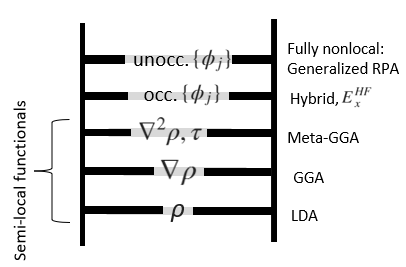

Figure 1: Approximations for exchange-correlation functional. Each        

                     rung includes as well dependence shown on all the lower rungs.    

              No xc functional $\epsilon_{xc}=0$ (as in Thomas-Fermi model), can be  

                                considered as zeroth rung of the Jacob's ladder.                                         

The first lowest three rungs are occupied by the so-called semi-local approximations.    

- First rung, **Local Density Approximation** (LDA): $\epsilon_{xc}$ depends on $\mathbf{r}$ only through the local electron density $\rho(\mathbf{r})$, $\epsilon_{\mathrm{xc}}(\mathbf r)= \epsilon_{\mathrm{xc}}(\rho(\mathbf{r}))$. LDA was introduced by [Kohn and Sham](https://journals.aps.org/pr/abstract/10.1103/PhysRev.140.A1133) when introducing their original implementation of DFT.

- Second rung, **Generalized Gradient Approximation** (GGA): $\epsilon_{xc}$ depends on electron density $\rho$ and magnitude of its gradient $\nabla \rho$, $\epsilon_{\mathrm{xc}}(\rho, \nabla \rho)$. The GGA functionals are the most widely used functionals, due to the favorable compromise between accuracy and computational cost. 

- Third rung, **Meta-GGA approximation** (MGGA): $\epsilon_{xc}$ depends on the Laplacian (second derivative) of the electron density $\nabla^2 \rho$ and/ or the kinetic-energy density of KS electrons $\tau=\frac{1}{2} \sum_{i=1}^N \nabla \phi_i^* \cdot \nabla \phi_i$, in addition to the electron density and its gradient: $\epsilon_{\mathrm{xc}}(\rho, \nabla \rho, \nabla^2 \rho, \tau)$.

-  Fourth rung introduces dependence on the occupied Kohn-Sham orbitals where exchange–correlation functional $E_{xc}$ is represented by the [hybrid functionals](https://en.wikipedia.org/wiki/Hybrid_functional). Here $E_{xc}$ is usually constructed as a sum of the Hartree–Fock exact exchange functional $E^{HF}_x$ (involving the occupied KS orbitals) and some other exchange and correlation explicit density functionals. The parameters determining the weight of each individual functional can be fitted to the experimental data. Hybrid functionals, in particular, reduce self-interaction error (caused by unphysical interaction of electron with its own charge).

- Fifth rung: **fully non-local functionals** are obtained from generalized random-phase approximation and include information from virtual (unoccupied) orbitals as well. 

Construction of accurate exchange-correlation functionals is an active area of research. Here, like in the live script on OFDFT for numerical implementation of radial KS-DFT we will use exchange-correlation functional from the lowest (first) rung of the Jacob's ladder, namely LDA-PZ implementation of local density approximation.

In live script *Applications of DFT* we showcase usage of two MATLAB-based toolboxes: KSSOLV and  M-SPARK, which use exchange-correlation functionals from higher rungs of the Jacob's ladder depicted in Fig. 1.

## Pseudopotential vs All Electron Formulations

When solving the Kohn-Sham equations for electronic systems such as molecules or solids, space can be divided into two regions. 

- The regions near the nuclei, the **core** regions, are composed primarily of tightly bound (strongly localized electrons with large binding energies to nuclei) core electrons which respond very little to the presence of neighboring atoms. 

- The remaining space contains the **valence** electrons (with smaller binding energies to neclei) which are much more delocalized tahn the core elecrtons and are responsible for the bonding together of the atoms. 		


The main difficulty in all electron method is that DFT involving large number of electrons could be very expensive. To study valence properties the pseudopotential method is proposed instead. Pseudopotential method is based on observation that core electrons appear to be rigid and do not affect valence electronic structure (bonds, excitations, band gaps, conductivity) much due to the different energy and length scales involved. Then idea is to

- Get rid of the core electrons and keep only the valence ones for KS-DFT 

- Represent the core electrons by an effective operator that valence electrons feel. This effective operator can be angular momentum dependent because of core states in $s$, $p$, $d$ angular momentum channels

The goal is to construct effective operator in such a way to represent the action of the core electrons as closely as possible to the true atom. Then we can save a lot of computation time for solving Kohn-Sham equations for large systems. Norm-Conserving pseudopotential method proposed by Hamann et. al. is widely adopted in practice. 

In live script *Applications of DFT* we showcase usage of  two MATLAB-based toolbox: KSSOLV and  M-SPARK, which use pseudopotentials and implement KS-DFT in momentum space and real-space respectively. We recommend readers to consult these toolboxes for deeper understanding of advanced techniques used in KS implementation of DFT.

## Two Types of Implementations for Kohn-Sham DFT

In practice, there are 2 types of implementation for Kohn-Sham solvers, in either **momentum space** or **real space**. 

### Momentum space

For periodic systems, such as solids, one can focus on one period, called a unit cell (choice of unit cell is not unique though), and solve KS Eqs. (12) restricted to this unit cell. Unit cell provides us with a finite computational box in real space with a lattice constant $\mathbf{h}=\left[\mathbf{a}_1, \mathbf{a}_2, \mathbf{a}_3\right]$ and (posiively defined) volume $\Omega=|\det[\mathbf{a}_1 \mathbf{a}_2 \mathbf{a}_3]|=|\mathbf{a}_1\cdot (\mathbf{a}_2\times\mathbf{a}_3 )|$. The [reciprocal lattice](https://en.wikipedia.org/wiki/Reciprocal_lattice) is defined as (in matrix notations) $\left[\mathbf{b}_1 \mathbf{b}_2 \mathbf{b}_3\right]^T=2\pi[\mathbf{a}_1 \mathbf{a}_2 \mathbf{a}_3]^{-1}$, with $\mathbf{b}_j \mathbf{a}_i=2\pi \delta_{ij}$. The direct lattice vectors are $\mathbf{L}=i \cdot \mathbf{a}_1+j \cdot \mathbf{a}_2+k \cdot \mathbf{a}_3$ and reciprocal lattice vectors are $\mathbf{G}=i \cdot \mathbf{b}_1+j \cdot \mathbf{b}_2+k \cdot \mathbf{b}_3$.

Bloch's theorem for periodic potentials (provided that ground state electron density is periodic as well) applied to KS equations implies that KS orbitals can be written as:


$$\phi_{j,\mathbf{k}}(\mathbf{r})=e^{i\mathbf{k} \mathbf{r}}u_{j,\mathbf{k}}(\mathbf{r}),\qquad (17)$$


where $u_{j,\mathbf{k}}(\mathbf{r})$ function has periodicity with a latice constant $\mathbf{h}$, coordinate $\mathbf {r}$ is restricted to the unit cell, and $\mathbf{k}$ is a crystal momentum vector in the first Brillouin zone. 

Because functions $u_{j,\mathbf{k}}(\mathbf{r})$ are periodic, they can be expanded in plane-wave basis functions, 


$$\varphi_{\mathbf{G}}(\mathbf{r})=\frac{1}{\sqrt{\Omega}} \exp \left[i \mathbf{G} \cdot \mathbf{r} \right],\qquad(18)$$


  
$$u_{j,\mathbf{k}}(\mathbf{r})=\frac{1}{\sqrt{\Omega}}\sum_{\mathbf G} c^{\mathbf{k}}_j(\mathbf{G})e^{i\mathbf{G} \mathbf{r}}, \qquad c^{\mathbf{k}}_j(\mathbf{G})=\frac{1}{\sqrt{\Omega}} \int_{\Omega}  u_{j, \mathbf{k}} (\mathbf{r}) e^{-i{\mathbf{G} \mathbf{r}}}  d\mathbf{r}. \qquad(19)$$


As in Hartree-Fock method, to solve Kohn-Sham equations numerically in momentum space, some basis functions sets are introduced. The **plane waves** in Eq. (18) represent natural choise fot the basis set in momentum space KS-DFT implementations. 

As we assumed charge density to be periodic, we can represent it as


$$\rho(\mathbf{r})=\frac{\Omega}{(2\pi)^3} \int_{\mathrm{BZ}} \rho_{\mathbf{k}} (\mathbf{r}) d\mathbf{k}, \qquad (20)$$


where


$$\rho_{\mathbf{k}}(\mathbf{r})= \sum_{j=1}^N  |\phi_{j,\mathbf{k}}(\mathbf{r}) |.\qquad (21)$$


In case of sufficiently large $\Omega$, the Brillouin zone is so small that one can retain only $\mathbf{k}=0$ point (known also as the $\Gamma$-point) in approximate evaluation of $\rho(\mathbf{r})$ in Eq. (20), $\rho(\mathbf{r})\simeq \rho_{0} (\mathbf{r})$.

Restricting to a single $\mathbf{k}=0$ point, and denoting $\phi_{j, \mathbf{0}}=\phi_j$ we can express the Kohn-Sham orbitals in terms of plane waves using Eqs. (17) and (19) as: 


$$\begin{array}{cc}\phi_j(\mathbf{r}) =\frac{1}{\sqrt{\Omega}} \sum_{\mathbf{G}} c_j(\mathbf{G}) \exp [i \mathbf{G} \cdot \mathbf{r}].& \qquad (22)\\ \end{array}$$


Plane waves, besides being orthonormal, $\left\langle\varphi_{\mathrm{G}^{\prime}} \mid \varphi_{\mathrm{G}}\right\rangle=\delta_{\mathrm{G}^{\prime}, \mathrm{G}}$ and having natural periodicity w.r.t. computational box $\mathbf{h}$, are eigen states of kinetic energy operator: 


$$\begin{array}{cc}-\frac{1}{2} \nabla^2 \varphi_{\mathbf{G}}(\mathbf{r})=-\frac{1}{2}(i G)^2 \frac{1}{\sqrt{\Omega}} \exp [i \mathbf{G} \cdot \mathbf{r}]=\frac{1}{2} G^2 \varphi_{\mathrm{G}}(\mathbf{r}),& \qquad (23)\\ \end{array}$$


with eigen value,


$$\begin{array}{cc}E_{\mathrm{kin}}(\mathbf{G})=\frac{1}{2} G^2& \qquad (24).\\ \end{array}$$


In practice, finite number of plane waves must be used, hence the energy cutoff is introduced, which is the upper bound of the kinetic energy, $\frac{1}{2} G^2 \leq E_{\mathrm{cut}}$.

By using plane waves, we can take advantage of properties of Fourier transforms, like Parseval’s theorem, and easily evaluate energies and other properties in momentum space. 

The Poisson's equation in periodic systems can be also easily solved in momentum space due to the relations (tilde on variable indicating Fourier transform)


$$\begin{array}{cc}\nabla^2 V_{\mathrm{H}}(\mathbf{r})=-4 \pi \rho (\mathbf{r}) \to \tilde V_{\mathrm{H}}(\mathbf{G})=4 \pi \frac{\tilde \rho(\mathbf{G})}{G^2}.& \qquad (25)\\ \end{array}$$


Fast algorithms, such as Fast Fourier Transform (FFT), can be used to speed up the code to transform the Kohn-Sham orbitals between real and momentum spaces, allowing to compute terms in Hamiltonian or charge density in the space which is the most computationally efficient. For example charge density is cheaper to calculate in real-space, by first transforming wave functions to real-space. 

In live script *Applications of DFT* we showcase usage of MATLAB-based toolbox KSSOLV that implements KS-DFT based on plane-wave basis in 3D, Ref. [5]. 

### Real space

In real space typically there are implementations of KS-DFT in finite element method and finite difference method. Here we only introduce the finite difference method that we will apply in our simplified 1D numerical implementation of radial KS-DFT below. In 3D implementations of finite difference method, usually uniform grid is used with spacings $h_x= h_y=h_z=h$ in all 3 directions, where $N_x, N_y, N_z$ are grid points along each direction. Then the Laplacian of any function $f$ at the grid point $(i, j, k)$ is approximated using [central finite difference](https://en.wikipedia.org/wiki/Finite_difference):


$$\begin{array}{cc}\left.\nabla_h^2 f\right|^{(i, j, k)} \approx \sum_{p=0}^{n_0} w_p\Big(f^{(i+p, j, k)}+f^{(i-p, j, k)}+f^{(i, j+p, k)}+f^{(i, j-p, k)}+f^{(i, j, k+p)}+f^{(i, j, k-p)}\Big),& \qquad (26)\\ \end{array}$$


where $f^{(i, j, k)}$ represents the value of the function $f$ at the node $(i, j, k)$. The weights $w_p$ are given by: 


$$\begin{array}{cc}\begin{array}{rll}& w_0=-\frac{1}{h^2} \sum_{q=1}^{n_0} \frac{1}{q^2}, \\& w_p=\frac{2(-1)^{p+1}}{h^2 p^2} \frac{\left(n_{0} !\right)^2}{\left(n_0-p\right) !\left(n_0+p\right) !}, p=1,2, \ldots, n_0 .\end{array}& \\ \end{array}$$


These finite-difference expressions for the Laplacian represent $O\left(h^{2 n_0}\right)$ accurate approximations. We use Dirichlet boundary condition to truncate the computational domain by setting $f^{(i, j, k)}=0$ for any index that does not correspond to a node in the finite-difference grid (if a node falls outside the boundaries of the grid). While performing spatial integrations, we assume that the function $f$ is constant in a cube of side $h$ around each grid point, i.e.,


$$\begin{array}{cc}\int_{\Omega} f(\mathbf{r}) \mathrm{d} \mathbf{r} \approx \mathrm{d}\Omega \sum_{i=1}^{N_x} \sum_{j=1}^{N_y} \sum_{k=1}^{N_z} f^{(i, j, k)},& \qquad (27)\\ \end{array}$$


where $\Omega=h^3N_d$ and $\mathrm{d}\Omega = \Omega/N_d$ (with $N_d=N_x\cdot N_y\cdot N_z$) is the 3D integration measure in real space. When solving the radial Kohn-Sham equations numerically below, we implement integrals and Laplacian with such discrete approximations for 1D radial space, after discretizing radial variable into $N_d$ points between $r=0$ and $r=R_{max}$.

In live script *Applications of DFT* we showcase usage of MATLAB-based toolbox M-SPARK that implements KS-DFT based on finite difference method in 3D, Ref. [6]. 

## Radial Kohn-Sham DFT

For the systems with spherically symmetric ground state electron density, like atoms with filled subshells, we have $\rho(\mathbf{r}) = \rho(r )$ and effective potential appearing in KS Eqs. (12) is spherically symmmetric $V_{eff}[\rho](\mathbf{r})=V_{eff}[\rho](r)$. 

In such situation, as we showed in live script *Spherically Symmetric Potential, *we can represent eigen states of Schrödinger equation (in the case of KS Eqs. (12), they are nonlinear Schrödinger equations) as $\phi_j(\mathbf{r})=\psi_{n\ell m}(\mathbf{r})=R_{nl}(r)Y_{\ell}^m(\theta, \phi)$, where $R$ and $Y$ satisfy Eqs. (19) and (20) respectively in live script *Spherically Symmetric Potential. *For simplicity *b*elow we will only concentrate on $\ell=m=0$ (hence $s$-states) KS orbitals, which show no angular dependence, and represent them as:


$$\begin{array}{cc}\phi_j(\mathbf{r}) = R_{n0}(r)Y_0^0 = \frac{1}{\sqrt{4\pi}}R_j(r).& \qquad (28)\\ \end{array}$$


In Exercise 1 we suggest reader to include KS orbitals with $\ell>0$. Solution to Exercise 1 is provided in a separate live script.

We introduce a new variable              


$$\begin{array}{cc}u_j(r) = rR_j(r).& \qquad (29)\\ \end{array}$$


Then KS Eqs. (12) can be written as a system of 1D equations


$$\begin{array}{cc}\hat \mathcal{H}_r u_j(r)=\lambda_j u_j(r), \quad \hat\mathcal{H}_r=-\frac{1}{2} \frac{\partial^2}{\partial r^2}+V_{eff}[\rho](r)=-\frac{1}{2} \frac{\partial^2}{\partial r^2} +V_{\mathrm{ext}}(r) + V_{\mathrm{H}}[\rho](r) + V_{\mathrm{xc}}[\rho](r).& \qquad (30)\\ \end{array}$$


The radial KS Eqs. (30) will be solved numerically below by the iterative Self-Consistent Field (SCF) method. SCF method is similar to the one that we discussed in live script *Hartree-Fock Approximation*. Before presenting the numerical solver, we present results that we obtain for the ground state energy and electron density for atoms with atomic number $Z$. Observe that we do not have any fitting parameter, as opposed to the case of OFDFT, where we used constant $\lambda$ in front of the von Weizsäcker functional (that we adjusted to $\lambda\sim 1/5$). Even without a fitting parameter, KS-DFT produces much more accurate results for ground state electron density for atoms than OFDFT, while ground state energies produced by both methods agree favorably with each other for low values of $Z$. In particular, for $Z>2$ KS-DFT reproduces typical for electrons additional bumps (more than 1) in the ground state radial electron density $4\pi \rho(r) r^2$, visualizing the shell structure of atoms. Simulation of helium ground state electron density using KS-DFT compares excellently with Hartree-Fock result. Both KS-DFT and HF methods are implemented for closed-shell systems in these notes and hence applied to helium atom they model ground state properties in a parahelium spin-singlet configuration, involving a single spatial orbital occupied by spin up and spin down electrons.  

## Radial KS-DFT Numerical Results 

We start with selecting parameters for simulating ground state energy and electron density of an atom using our radial KS-DFT numerical solver that is provided in code section below.

First we select the atom index $Z$. Since with increasing $Z$ more eigen states and eigen values need to be calculated, and since for simplicity we retained in this script only $s$-orbitals (see Excercise 1 for retaining nonzero $\ell$ orbitals), accuracy of our numerical solver degrades quickly with increasing value of $Z$. 

Z = 2;

Next, we set up the following parameters: 

- The maximum radial length $R_{max}$ - simulation "box" size in Bohr radius units. 

- Number of grid points in radial direction $N_d$. Simulations on system sizes of up to $N_d=2000$ for generic $Z$ with `tol=`$10^{-3}$ is possible within a few seconds for `maxit=5000` on line 136. For helium atom $N_d=7000$ is possible for $R_{max}=30$ within couple of minutes and leads to $E_0= -78.79eV$ for `tol=`$10^{-3}$ and FDn=2.

- Order of finite difference approximation `FDn.` We use [central finite differences](https://en.wikipedia.org/wiki/Finite_difference) for discrete approximations of derivatives. 

- Convergence tolerance `tol`: setting a threshold for the difference between total energies obtained in the current and previous steps of iteration. Once the difference becomes lower than tolerance, iteration stops.

R_MAX = 30;
Nd = 2000;
FDn = 4; 
tol = 1e-4; 

Now we run our simple radial Kohn-Sham DFT code. 

S_DFT = SCF(init_DFT(Z,R_MAX,Nd,tol,FDn));

Total energy in 1 step -2.591343 Ha
Total energy in 2 step -2.996543 Ha
Total energy in 3 step -2.825617 Ha
Total energy in 4 step -2.897197 Ha
Total energy in 5 step -2.866838 Ha
Total energy in 6 step -2.879668 Ha
Total energy in 7 step -2.874236 Ha
Total energy in 8 step -2.876534 Ha
Total energy in 9 step -2.875561 Ha
Total energy in 10 step -2.875973 Ha
Total energy in 11 step -2.875799 Ha
Total energy in 12 step -2.875872 Ha
Finished SCF in 12 steps!

Energy decomposition 
Ek   =   2.717351 Ha
Eh   =   1.903581 Ha
Exc  =  -0.964100 Ha
Eext =  -6.532704 Ha
Etot =  -2.875872 Ha, -78.256537 eV


While radial KS-DFT code is running, total energy is printed in real time, after each iteration. After the calculations converge, the total ground state energy, together with its decomposition into different contributions, are shown. For simulation "box" size $R_{max}=30$, the ground state energies are within $\sim1\%$ of error with the results reported in the literature for low values of $Z=2,3,4$, even though that system sizes we can simulate are quite small (up to $N_d \simeq 2000$) and we use LDA for xc for atoms. For larger $Z$ accuracy deteriorates, e.g. for cabron atom $Z=6$ we obtain for $N_d=2000$, $E_0\simeq-987eV$, result that is already $4\%$ off the reported value of $-1030eV$. 

Next, we plot the ground state radial electron density $4\pi \rho(r )r^2=4\pi \rho_{\uparrow}(r)r^2+4\pi \rho_{\downarrow}(r)r^2$. For $Z=1$ and $Z=2$, together with KS-DFT results we also plot ground state electron densities obtained from the exact solution and Hartree-Fock approximations correspondingly. Note, for $Z\ge 3$ additional bumps are visible in radial probability distribution $4\pi r^2\rho(r )$, corresponding to different electron shells. This feature (very typical to fermions bumps, see live script on *Hydrogen Atom*, where we discuss shell model of atom) is not observable in our OFDFT simulations. In Exercise 2 the reader is suggested to obtain similar plots for spin-resolved radial ground state electron densities $4\pi \rho_{\uparrow}(r)r^2$ and $4\pi \rho_{\downarrow}(r)r^2$ for lithium atom.

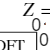

figure
hold on
plot([0;S_DFT.r],[0;4*pi*S_DFT.rho.*S_DFT.r.^2])  % adding r=0 point
load HFrho
if Z==2
    plot(HFrho.x,HFrho.y);
    legend("KS-DFT ","HF ",'Interpreter','latex')
else 
    legend("KS-DFT $\rho$",'Interpreter','latex')
end
hold off

xlabel("$r$ (Bohr)",'Interpreter','latex')
ylabel("$4\pi \rho(r) r^2$",'Interpreter','latex')
xlim([0 6*Z^(1/3)])
title("Radial electron density",'Interpreter','latex')
subtitle(['$Z=$',num2str(Z)],'Interpreter','latex')
box on

if Z==1 
    hold on
    syms rh
    fplot(4*rh^2*exp(-2*rh))
    xline(1)
    xlim([0 6])
    legend("Converged KS-DFT","Hydrogen exact",'Interpreter','latex')
    hold off
end

Next, we plot external potential $V_{\mathrm{ext}}(r)$ and converged Hartree $V_{\mathrm{H}}[\rho_{converged}](r)$ as well as exchange-correlation potential $V_{\mathrm{xc}}[\rho_{converged}](r)$. 

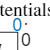

figure
yyaxis left
plot(S_DFT.r,S_DFT.Vh)
hold on
plot(S_DFT.r,S_DFT.Vx+S_DFT.Vc)
hold off
yyaxis right
plot(S_DFT.r,S_DFT.Vext)
legend("$V_H$","$V_{XC}$","$V_{ext}$",'Interpreter','latex')
xlabel("$r$ (Bohr)",'Interpreter','latex')
xlim([0 5])
title("Potentials $V$",'Interpreter','latex')
box on
hold off

And lastly we plot the converged effective potential $V_{\mathrm{eff}}=V_{\mathrm{ext}}+V_\mathrm{H}+V_{\mathrm{xc}}$

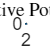

figure
plot(S_DFT.r,S_DFT.Vh+S_DFT.Vx+S_DFT.Vc+ S_DFT.Vext)
xlim([0.2,5])
ylabel("$V_{eff}\,\,[\rho](r)$",'Interpreter','latex')
xlabel("$r$ (Bohr)",'Interpreter','latex')
title( "Effective Potential",'Interpreter','latex')

## Simple Numerical Solver for Radial Kohn-Sham DFT

This last section includes numerical solver for radial KS-DFT, starting by implementing Hamiltonian in Eq. (33). We will implement a real-space finite-difference method to discretize the KS equation where the Laplacian operator is represented by high-order differences. After spatial discretization, a derived nonlinear eigenvalue problem is solved by a self-consistent field (SCF) iteration scheme with the update of electron density and potentials. In spite of the simplicity and versatility of the finite-difference method, one has to perform large-scale calculations of both eigen value and electrostatic problems at each iteration step. We use Dirichlet boundary condition to truncate the computational domain. 

Note that, after discretizing the radial direction, $u_j(r)$ are implemented numerically as an $N_d$-dimensional columnar vectors $u_j(r )\to\{  u_j(r_1), u_j(r_2),...,u_j(r_{N_d}) \}$, whereas Hamiltonian is represented by $N_d$x$N_d$ square matrix. One way to implement Hamilton matrix is to use sparse data type and define: `H_sparse = sparse(-1/2*S.Lap + diag(S.Veff)),` however, as in the case of OFDFT, we store action of Hamilton (matrix) on state (vector) Eq. (30), instead of storing Hamilton matrix separately. 

function Hr_uk = Hamiltonian(S,uk)
% Hamiltonian times vector routine, uj is a columnar vector with Nd entries
% S.Lap is NdxNd (sparse) matrix and S.Veff is columnar vector with Nd entries
    
    Hr_uk = -1/2*S.Lap*uk + S.Veff.*uk;
end

We call the sum $V_{\mathrm{ext}}(r) + V_{\mathrm{H}}[\rho](r) + V_{\mathrm{xc}}[\rho](r)$ the effective potential $V_{\mathrm{eff}}[\rho](r)$. Note that, after discretizing the radial direction, all potentials numerically are stored as an $N_d$-dimensional columnar vectors, for example ${V}_{ext}(r)\to \{V_{ext} (r_1),  V_{ext} (r_2),..., V_{ext} (r_{N_d})\}$.

function S = compute_effective_potential(S,rho)

    S.Vh = compute_hartree_potential(S,rho);
    % rho(rho < 1e-10) = 1e-10;    % avoiding region with vanishing density in case of need
    [S.Ex,S.Vx] = slater(rho);     % exchange contribution in energy and effective potential
    [S.Ec,S.Vc] = pz(rho);         % Perdew-Zunger correlation contribution, Ref.[7], in energy and effective potential
    
    S.Veff = S.Vext + S.Vh + S.Vx + S.Vc;  % total effective potential 
    % S.Vext is created during the initialization of structure variable S
end

The electron density becomes 


$$\begin{array}{cc}\rho(r) = \frac{1}{4\pi}\sum_{i=1}^NR_i^2(r) = \frac{1}{4\pi}\sum_{i=1}^N \frac{u_i^2(r)}{r^2}, & \\ \end{array}$$


where $N/2$ lowest energy KS orbitals are occupied by spin up and spin down electrons in the ground state in case of even $N$. Index $i$ runs twice through each occupied lowest energy $N/2$ orbitals $u_i$: once for capturing contribution from spin up electrons in total density and another time for spin down electrons. Hence in our denotions we have duplications in orbitals $u_1=u_2$, $u_3=u_4$, etc. We will below assume that index $k$ runs only once through each occupied KS orbitals and redefine $u_1=u_2 \to u_1$, $u_3=u_4 \to u_2$,...  to obtain:

$\rho(r) =  \displaystyle\begin{cases}  \frac{1}{2\pi}\sum_{k=1}^{N/2} \frac{u_k^2(r)}{r^2},& \text{for \, even\,} N,\\ \frac{1}{2\pi}\sum_{k=1}^{(N-1)/2} \frac{u_k^2(r)}{r^2}  +\frac{1}{4\pi} \frac{u_{N_{band}}^2(r)}{r^2}, &  \text{for \, odd\,}  N, \end{cases}$        (31)

where $N_{band}=(N+1)/2$.

function rho = electron_density(S,u) 

    R = u./S.r;  % both R and u are NdxNband matrices with Nband columns, S.r is a columnar vector with Nd entries
    rho = sum(R.^2.*S.occ,2)/(4*pi);
end

As in OFDFT, Hartree potential can be obtained by solving Poisson equation (and applying "inverse" of 1D Laplacian to both sides of it)


$$\varphi''(r) = -4\pi r \rho(r),\qquad(32)$$


where $\varphi = rV_{\mathrm{H}}(r )$.

After discretizing radial space in $N_d$ points, both $\varphi$ and $V_H$, similar to $\rho$, are implemented numerically as $N_d$-dimensional columnar vectors.

function Vh = compute_hartree_potential(S,rho)
% Computes Hartree potential from solving the Poisson equation
    % phi''(r) = -4pi*r*rho(r), where Vh = phi/r
    phi = S.Lap\(-4*pi*rho.*S.r);  % note the left divide sign \ for solving Eq. (32), instead of inversing sparce matrix S.Lap
    Vh = phi./S.r;  % Vh, phi, rho, and S.r are columnar vectors with Nd entries
end

To evaluate integral of a spherically symmetric function $f$ over $\mathbf{R}^3$ we pass to spherical cordinates and use:


$$\begin{array}{cc}\int f(\mathbf{r} ) d \mathbf{r}  = 4\pi \int_0^{\infty} f(r) r^2 dr& \\ \end{array}$$


and approximate integral with a discrete sum over the 1D radial grid.

function intf = int3d(S,f)
% compute integral of function in R3 in spherical coordinate
% assuming f is spherically symmetric
    
    intf = 4*pi*S.h*sum(f.*S.r.^2);
end

In terms of $u_i(r)$ kinetic energy reduces to 


$$T=-\frac{1}{2}\sum_{i=1}^N\int u_i(r)u^{''}_i(r) dr.$$


Redefining again $u_1=u_2 \to u_1$, $u_3=u_4 \to u_2$,... as for the case leading to Eq. (31), we rewrite kinetic energy as:

 $T =  \begin{cases}  -\sum_{k=1}^{N/2}\int u_k(r)u^{''}_k(r) dr  ,& \text{for \, even\,} Z\\   -\sum_{k=1}^{(N-1)/2}\int u_k(r)u^{''}_k(r) dr   - \frac{1}{2}\int u_{N_{band}}(r)u^{''}_{N_{band}}(r) dr  , &  \text{for \, odd\,}  Z. \end{cases}$      (33)

We will calculate total energy using Eq. (15) that we rewrite for the ground state configurations of closed-shell KS systems as follows: 

- For even $N$ redefining: $\lambda_1=\lambda_2 \to \lambda_1< \lambda_3=\lambda_4 \to \lambda_2< ,..., <\lambda_{N-1}=\lambda_{N}\to \lambda_{N/2}$ and $u_k$-s similarly, we calculate electron density from Eq. (31), and then total energy as: $E=2\sum_{k=1}^{N/2} \lambda_{k}-E_{\mathrm{H}} -\int V_{\mathrm{xc}}(\mathbf{r}) \rho(\mathbf{r}) d \mathbf{r}+E_{\mathrm{xc}}.$

- For odd $N$redefining: $\lambda_1=\lambda_2 \to \lambda_1 < \lambda_3=\lambda_4 \to \lambda_2< ,..., <\lambda_{N} \to \lambda_{N_{band}}$ and $u_k$-s similarly, we calculate electron density from Eq. (31) and $E=2\sum_{k=1}^{(N-1)/2} \lambda_{k}+\lambda_{N_{band}}-E_{\mathrm{H}} -\int V_{\mathrm{xc}}(\mathbf{r}) \rho(\mathbf{r}) d \mathbf{r}+E_{\mathrm{xc}}.$

function S = energy(S)
% compute all energies
    S.Ek = sum(sum((-1/2*S.Lap*S.u).*S.u).*S.occ)*S.h; % discrete approximation to Eq. (33)
    S.Eext = int3d(S,S.Vext.*S.rho);
    S.Eh = 1/2*int3d(S,S.Vh.*S.rho);
    S.Exc = int3d(S,(S.Ex+S.Ec).*S.rho);
    S.Exc_dc = int3d(S,(S.Vx+S.Vc).*S.rho);
    S.Etot = sum(S.occ.*S.Eband') - S.Eh - S.Exc_dc + S.Exc; % Eq. (15)
end

The normalization condition on electron density for neutral atom becomes


$$\begin{array}{cc}4\pi \int \rho(r)r^2 dr = Z& \\ \end{array}$$


and orthonormality of wave functions reduces to


$$\begin{array}{cc}\int R_i(r) R_j(r) r^2 dr = \int u_i(r) u_j(r) dr = \delta_{ij}.& \\ \end{array}$$


It is convenient for numerical implementation to define matrix $u$ with $N_d$ rows and $N_{band}$ columns, where $N_{band}$ is number of different occupied KS orbitals in the ground state


$$N_{band} =  \begin{cases} \frac{Z}{2},& \text{for \, even\,} Z,\\ \frac{Z+1}{2}, &  \text{for \, odd\,}  Z. \end{cases}$$


Each column of matrix u is a different vector $u_k$ with $N_d$ entries, and $k=1,2,...N_{band}$.          

We define function `normalize` that rescales each column of matrix $u$ as $\sum_{i=1}^{N_d} u_k(r_i) u_k(r_i) \Delta r=1$, hence $(\vec{u_k} \cdot \vec {u_k} )=1/\Delta r$ for any $k$.

function u = normalize(S,u)
% rescales radial wave function, u is NdxNband matrix (with Nd rows and Nband columns) 
    
    scale = S.h*sum(u.^2,1);   % S.h= Delta r
    u = u ./ sqrt(scale);
    % so that S.h*u(:,j)'*u(:,j)=1, hence each column of u is normalized to 1/S.h
end

## Self-Consistent Field

The system of Kohn-Sham equations (Eqs. (12) and (33)) is a nonlinear eigenvalue problem, which can not be solved directly. We use the Self-Consistent Field (SCF) method, similar to one that we presented in Hartree-Fock method. In Fig. 2 we sektch the algorithm of the SCF method.

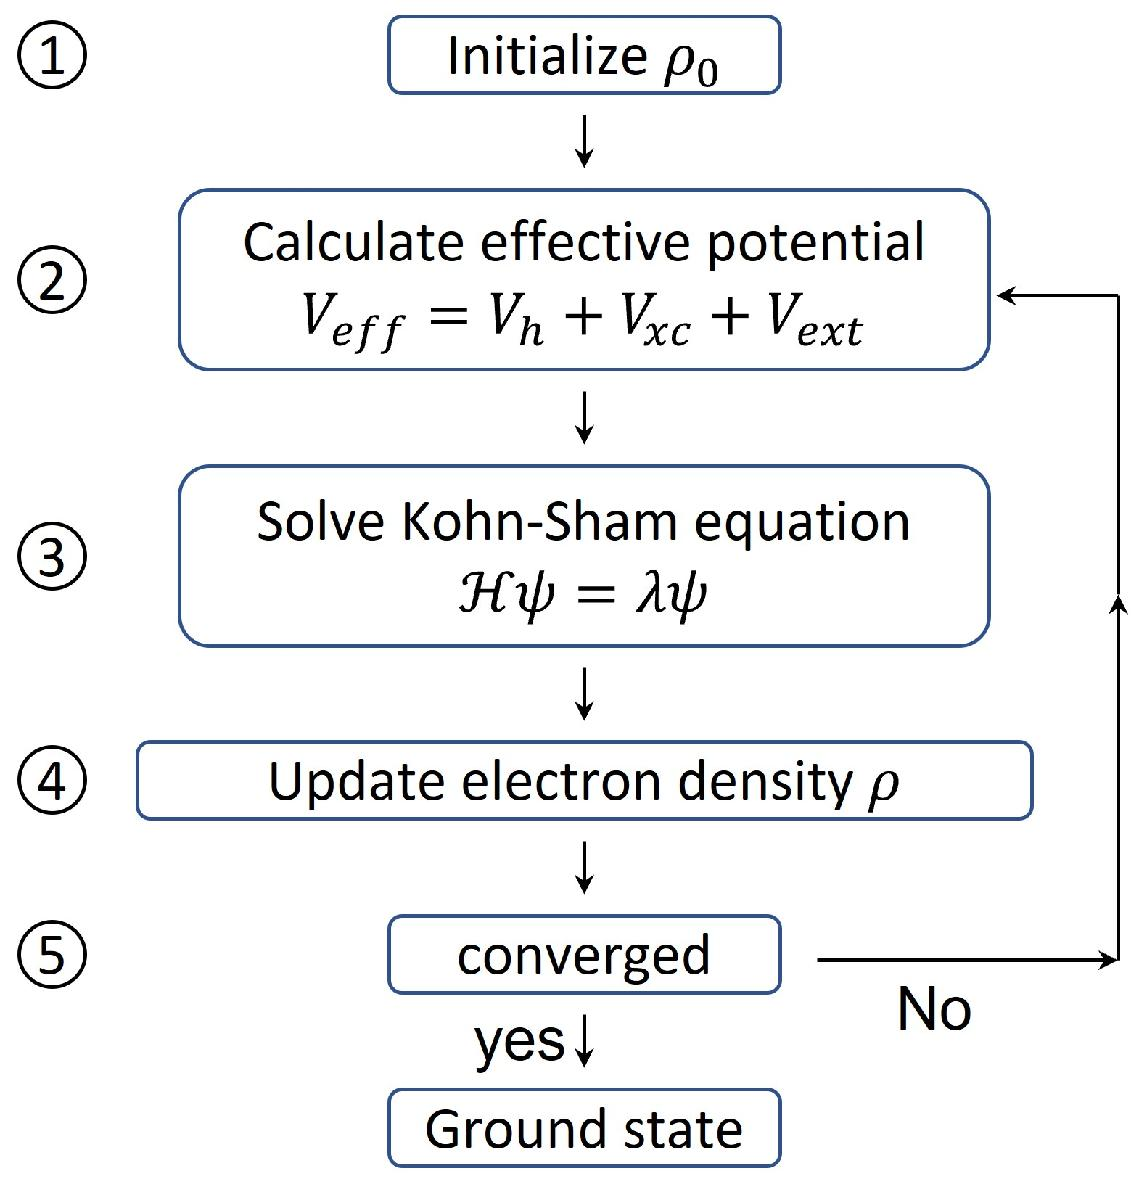

Figure 2: Steps of KS SCF method.

function S = SCF(S)
% self-consistent field method for solving the radial Kohn-Sham eqution

**Step 1:** intializing the electron density by using 1s wave function.

    % initial 1s wave function and electron density 
    R0 = exp(-S.Z*S.r);
    S.u = normalize(S,R0.* S.r);      %Eq. (29): u=r*R
    S.rho = electron_density(S,S.u);
    
    % SCF parameters
    Etot_prev = 1; % some initial value
    S.Etot = 0;    % some initial value, but different from Etot_prev
    step = 0;
    maxstep = 3000;

Here is the control of the SCF by using the difference between total energies, obtained in two consequtive iteration steps, as convergence criteria (this is **Step 5 **in Fig. 2).

    while abs(Etot_prev-S.Etot)>S.tol && step < maxstep  % while both conditions are true loop will iterate
        Etot_prev = S.Etot;

**Step 2:** Calculate effective potential for the current Hamiltonian.

        S = compute_effective_potential(S,S.rho);

**Step 3:** Solve Kohn-Sham equation. 

        [S.u,S.Eband] = eigSolve(S);

 **Step 4:** Update electron density $\rho(r)$ using  Eq. (31) with eigen functions $u_k$ obtained in Step 3, and using updated density, together with eigen values $\lambda_k$ (also obtained in Step 3), compute the total energy as: 


$$E =  \begin{cases} \sum_{k=1}^{N/2} 2\lambda_{k}-E_{\mathrm{H}} -\int V_{\mathrm{xc}}(\mathbf{r}) \rho(\mathbf{r}) d \mathbf{r}+E_{\mathrm{xc}}   ,& \text{for \, even\,} N,\\  \sum_{k=1}^{(N-1)/2} 2\lambda_{k} +\lambda_{(N+1)/2}-E_{\mathrm{H}} -\int V_{\mathrm{xc}}(\mathbf{r}) \rho(\mathbf{r}) d \mathbf{r}+E_{\mathrm{xc}}, &  \text{for \, odd\,}  N. \end{cases}$$


To avoid large charge redistribution from one iteration to the next, a few density-mixing schemes (mixing new and old densities at each iteration) are developed. We will follow here the simple approach that does not involve density mixing and yet the ground state energies, as well as ground state electron densities, agree favorably with the results reported in the literature for low values of $Z$. In Exercise 3 reader is encouraged to implement simple damping scheme by modifying value of variable `beta` below. Note, if we include KS orbitals with nonzero $l$, convergence in general will not be achieved without nonzero damping, see Exercise 1.

        beta=0.0;         % try beta=0.9 
        S.rho = (1-beta)*electron_density(S,S.u)  +beta*S.rho;  % density update
        S = energy(S);    % S.Etot update
        step = step + 1;
        fprintf("Total energy in %d step %.6f Ha\n", step, S.Etot);
    end
    fprintf('Finished SCF in %d steps!\n', step);
    fprintf("\nEnergy decomposition \n");
    fprintf("Ek   = %10.6f Ha\n", S.Ek);
    fprintf("Eh   = %10.6f Ha\n", S.Eh);
    fprintf("Exc  = %10.6f Ha\n", S.Exc);
    fprintf("Eext = %10.6f Ha\n", S.Eext);
    fprintf("Etot = %10.6f Ha, %10.6f eV\n", S.Etot, S.Etot * 27.2114079527);
end

Kohn-Sham equation is an eigenvalue problem. Since we have decided to implement instead of Hamilton matrix, action of Hamilton natrix on $N_d$-dimensional vector $\vec {u_k}$, we define function handle Hfun that [`eigs` function](https://www.mathworks.com/help/matlab/ref/eigs.html) will accept.

function [u,Eband] = eigSolve(S)
% solve eigenvalue problem and rescale KS wave functions
    
    opts = struct(maxit=5000, tol= S.tol, isreal=1);
    Hfun = @(x) Hamiltonian(S,x);  
    [u,Eband] = eigs(Hfun,S.Nd,S.Nband,'smallestreal',opts);

Variable `u` that is returned by `eigs` function is a matrix with `S.Nd` rows and `S.Nband` columns.  Each column of `u` is $u_k$ vector (KS orbital) $\hat \mathcal{H}_ru_k=\lambda_k u_k$ and for different $k$ vectors $u_k$ orthogonal to each other e.g. `u(:,1)'*u(:,2)=0`. For same $k$ they are unit normalized, `u(:,k)'*u(:,k)=1.`

`Eband `is a diagonal matrix with $\lambda_k$ values on diagonal, with the smallest` Eband(1,1)=`$\lambda_1$.

    % H_sparse = sparse(-1/2*S.Lap + diag(S.Veff));          % equivalent way: implement Hamiltonian as a sparse matrix
    % [u,Eband] = eigs(H_sparse,S.Nband,'smallestreal',opts);  
    % comment out lines 136 & 137 and uncomment lines 139 & 140. You will get same result.
    
    Eband = diag(Eband);  % Eband becomes a columnar vector with S.Nband entries, with Eband(1)=lambda_1
    
    u = normalize(S,u); 
    % after this step, normalization of each column of u changes to
    % u(:,j)'*u(:,j)=1/S.h, so that S.h*u(:,j)'*u(:,j)=1
end

Following function called `init_DFT` is the initialization function to set up parameters for the Kohn-Sham problem. 

function S = init_DFT(Z,R_MAX,Nd,tol,FDn)
% Structure S picks up 11 fields after initialization
    S = struct();
    S.Z = Z;
    S.Nd = Nd;
    S.h = R_MAX/Nd;  % Delta r, integration measure in radial direction
    S.r = linspace(S.h,R_MAX,Nd)'; % radial vector space, S.r is columnar vector with Nd entries
    S.FDn = FDn;
    S.tol = tol;

In this example, like in the case of Hartree-Fock method, we neglect spin and assume that each orbital is occupied by 2 electrons with opposite spins, except of the last (highest energy) occupied orbital that is singly occupied for odd $N$. 

    S.Nband = ceil(S.Z/2);  % number of occupied different KS orbitals that is Z/2 for even Z and (Z+1)/2 for odd Z
    S.occ = [2*ones(1,floor(S.Z/2)) ones(1,mod(S.Z,2))];  % occupation numbers of orbitals 

All orbitals, except of the last one for odd Z (the highest energy one), is doubly occupied. For odd Z last orbital is singly occupied in the ground state, e.g. if `S.Z=7` then `S.occ=[2 2 2 1].`

    S.Etot = 0; % total energy set to zero, some initial value
    
    % potential that does not change once initialized
    S.Vext = - S.Z./ S.r; % initializing external (nuclear) potential
    
    % Laplacian (second derivative) matrix in 1D
    S.Lap = Laplacian(S.FDn,S.Nd,S.h);
end

Below are pair of functions (`slater` and `pz`) implementing LDA exchange and LDA-PZ correlation functional and potential.

%%%%%%% exchange correlation functions %%%%%%%

function [ex,vx] = slater(rho)
% slater exchange
    
    % rho, electron density
    % ex, exchange energy density 
    % vx, exchange potential 
    
    C2 = 0.73855876638202; % 3/4*(3/pi)^(1/3)
    C3 = 0.9847450218427;  % (3/pi)^(1/3)
    ex = - C2 * rho.^(1./3.);
    vx = - C3 * rho.^(1./3.);
end

function [ec,vc] = pz(rho)
% pz correlation: Perdew-Zunger implementation of LDA correlation energy and potential
    
    % rho, electron density
    % ec, correlation energy density 
    % vc, correlation potential
    
    A = 0.0311;
    B = -0.048;
    C = 0.002;
    D = -0.0116;
    gamma1 = -0.1423;
    beta1 = 1.0529;
    beta2 = 0.3334;
    
    % compuatation
    ec = zeros(size(rho,1),1);
    vc = zeros(size(rho,1),1);
    rs = (0.75./(pi*rho)).^(1.0/3.0) ;
    islt1 = (rs < 1.0);
    lnrs = log(rs(islt1));
    sqrtrs = sqrt(rs(~islt1));
    ec(islt1) = A * lnrs + B + C * rs(islt1) .* lnrs + D * rs(islt1);
    ox = 1.0 + beta1*sqrtrs + beta2*rs(~islt1);
    ec(~islt1) = gamma1 ./ ox;
    vc(islt1) = lnrs.*(A + (2.0/3.0)*C*rs(islt1)) + (B-(1.0/3.0)*A) + (1.0/3.0)*(2.0*D-C)* rs(islt1);
    vc(~islt1) = ec(~islt1) .* (1 + (7.0/6.0)*beta1*sqrtrs + (4.0/3.0)*beta2*rs(~islt1)) ./ ox;
end

Finally function `Lap` implements discrete Laplacian using central finite difference method. See more information at [https://en.wikipedia.org/wiki/Finite_difference_coefficient](https://en.wikipedia.org/wiki/Finite_difference_coefficient).

%%%%%%% finite difference functions %%%%%%%

function Lap = Laplacian(FDn,Nd,h)
% generate the sparse 1D Laplacian matrix
    
    % FDn, half order of accuracy
    % Nd, number of grid points
    % h, mesh 
    
    w2 = w2_c(FDn);
    e = ones(Nd,1)/h^2;
    Lap = spdiags(w2(1)*e,0,Nd,Nd);
    for i = 1:FDn
        Lap = Lap + spdiags(w2(i+1)*e,i,Nd,Nd);
        Lap = Lap + spdiags(w2(i+1)*e,-i,Nd,Nd);
    end
end

function w2 = w2_c(FDn)
% generate central finite difference coefficients for second order derivative
    
    % FDn, half order of accuracy
    % w2, central finite difference coefficients
    
    w2 = zeros(1,FDn+1) ;
    for k=1:FDn
	    w2(k+1) = (2*(-1)^(k+1))*(factorial(FDn)^2)/...
		    (k*k*factorial(FDn-k)*factorial(FDn+k));
	    w2(1) = w2(1)-2*(1/(k*k));
    end
end

## ** Exercises**

**Exercise 1: **Include in KS Eqs. (30) orbitals with non-zero angular momentum $\ell$: $\phi_j(\mathbf{r}) = R_{n\ell}(r)Y_{\ell}^m(\theta, \phi)$. 

Take case of neutral neon atom with $Z=10$ and distribute electrons in the ground state so that $1s$, $2s$, and $2p$ shells are filled by 2, 2, and 6 electrons respectively. Ground state electron density is spherically symmetric in closed-shell system due to relation: $\displaystyle\sum^l_{m=-\ell} Y_{\ell}^{m *}(\theta ,\phi) Y_{\ell}^{m }(\theta ,\phi)=\frac{2\ell+1}{4\pi}$. Calculate ground state energy in such configuration and compare the result with:

- reported in the literature ground state energy of neon, sum of all of its [ionization energies](https://en.wikipedia.org/wiki/Ionization_energies_of_the_elements_(data_page)): $E_0 \simeq -3512eV$

- the result that follows from our numerical implementation of KS-DFT, where only $s$-orbitals are retained 

- the result of our orbital-free implementation of DFT for neon: $E_0\simeq -3505eV$ for $N_d=6000$

Hint: For KS orbitals with $\ell>0$ (denoted with tilde variables below) you have to modify radial Hamiltonian to: 


$$\hat\tilde \mathcal{H}_r \tilde u_{i}(r)=-\frac{1}{2 } \frac{d^{2}\tilde u_{i}(r)}{d r^{2}}+\left[V_{eff}[\rho](r)+\frac{1}{2 } \frac{\ell(\ell+1)}{r^{2}}\right] \tilde u_{i}(r)=\tilde \lambda_{i} \tilde u_{i}(r).\qquad (33)$$


 Define 2 separate Hamiltonians, one for calculating $1s$ and $2s$ KS wave functions (as we have done in the script Eq. (30)) and their eigen values ($\lambda_1$ and $\lambda_2$) and another Hamiltonian as in Eq. (33), for calculating $2p$ KS wave function with $\ell=1$: $\tilde u_1, \tilde u_2,...$ and their eigen values $\tilde \lambda_1, \tilde \lambda_2,...$ (ordered in increasing order starting from the lowest eigen value). Then calculate total ground state energy as: $E_0=2\lambda_1+2\lambda_2 +6\tilde \lambda_1-E_{\mathrm{H}} -\int V_{\mathrm{xc}}(\mathbf{r}) \rho(\mathbf{r}) d \mathbf{r}+E_{\mathrm{xc}}$. To calculate  total electron density define Nband=3 and  `S.occ=[2 2 6].` 

Note, to help convergence of algorithm here it is essential to mix densities during updates, hence select nonzero value of `beta` in line 119, say `beta=0.2. `

We provide numerical implementation in a live script *Solving Radial Kohn-Sham Equations Including *$\ell=1$* Orbitals*, in case you need to consult a solution.

**Exercise 2: **In closed-shell formulation of KS-DFT, in case of even $Z$ the ground state electron density of spin up and spin down electrons are same: $\rho_{\uparrow}(r )= \rho_{\downarrow}(r ) =\rho( r)/2$. Take $Z=3$ lithium atom, and assume that in the ground state two electrons have spin up and only one electron has spin down (hence the singly occupied, the highest energy occupied KS orbital has spin up). Calculate $\rho_{\uparrow}(r )$ and $\rho_{\downarrow}(r )$ separately numerically, with $\rho(r )=\rho_{\uparrow}(r )+\rho_{\downarrow}(r )$. Then plot $4\pi r^2\rho_{\uparrow}(r )$ and $4\pi r^2\rho_{\downarrow}(r )$ in the same figure. Which one has a bump and explain why on physical grounds. 

Hint: for calculating $\rho_{\downarrow}(r )$ you will need only the lowest energy KS orbital ($1s$ orbital), whereas for $\rho_{\uparrow}(r )$ you will need the lowest energy KS orbital as well as next to the lowest energy one (both $1s$ and $2s$ KS orbitals).

**Exercise 3:** Implement simple density update damping scheme, by modifying value of `beta` to `beta=0.9` and then to `beta=0.95` in line 119 and calculate ground state energy and radial electron density for $Z=1,2,3$. Observe how results change. 

----------------------------------------------------------------------------------------------------------------------------------------------------------

[*] Note that, even though it is expressed in terms of KS orbitals, the Kohn-Sham kinetic energy functional $T_{KS}$ is still functional of electron density $\rho$, since the density unambiguously determines KS orbitals, in case density is noninteracting $v$-representable (main assumption of KS-DFT). That is why it is written as $T_{KS}[\rho]$.

[**] In our numerical implementation of the KS-DFT we assume the simple form for $E_{\mathrm{xc}}[\rho]$, namely that $\epsilon_{\mathrm{xc}}$ depends on $\mathbf r$ through $\rho(\mathbf{r})$ only - known as the [local density approximation ](https://en.wikipedia.org/wiki/Local-density_approximation)and hence $E_{\mathrm{xc}}[\rho] = \int \epsilon_{\mathrm{xc}}(\rho(\mathbf{r}))\rho(\mathbf{r}) d\mathbf{r}$, similar to the orbital-free implementation of DFT in live script *OFDFT*.  

----------------------------------------------------------------------------------------------------------------------------------------------------------

## References

1. L. Lin, J. Lu, and L. Ying, [*Numerical methods for Kohn–Sham density functional theory*](https://par.nsf.gov/servlets/purl/10146743)*, pp. 405-539, *Acta Numerica  (2019).

2. R. G. Parr and W. Yang, *Density-Functional Theory of Atoms and Molecules*, Oxford University Press, (1995).

3. R. M. Dreizler and E. K. U. Gross, *Density Functional Theory: An Approach to the Quantum Many-Body Problem, *Springer Science & Business Media (2012).

4. R. M. Martin, *Electronic structure, Basic Theory and Practical Methods*, Cambridge University Press, (2020).

5. S. Jiao et al. *KSSOLV 2.0: An efficient MATLAB toolbox for solving the Kohn-Sham equations with plane-wave basis set,* Computer Physics Communications, 279: 108424 (2022).

6. S. Ghosh and P. Suryanarayana, *SPARC: Accurate and efficient finite-difference formulation and parallel implementation of density functional theory: Isolated clusters*, Computer Physics Communications,  212: 189-204 (2017).

7. [Kieron Burke and Friends](https://dft.uci.edu/doc/g1.pdf), *The ABC of DFT*, Department of Chemistry, University of California, Irvine.

8. J. P. Perdew and A. Zunger, [*Self-interaction correction to density-functional approximations for many-electron systems*](https://journals.aps.org/prb/pdf/10.1103/PhysRevB.23.5048)*,* Phys. Rev. B **23**, 5048 (1981).